# COMSOL Plotter

Goal of this code is to extract and plot COMSOL outputs, manipulating them in ways not possiple with COMSOL


cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\COMSOL Analysis'

addpath( ...
    'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1', ... % Time domain analysis from GaN paper
    'G:\My Drive\Code\LTSpice\200825 xGAN xGEM Load Responses V1\', ...  % LT Spice output response
    'C:\Users\johns\Documents\Github\QEM-MATLAB', ...    % Access to generic libraries
    'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\SMA Injection'); %new comsol stuff
    

load('ImpVariables.mat')


## File Setup

freqMin = 0.05*c.giga;
freqMax = 10*c.giga;
freqStep = 0.05*c.giga;
field.freq = freqMin:freqStep:freqMax;
sizeAr = size(field.freq)

sizeAr =      1   200


## Port Voltage Input

filename = 'portVoltage.txt'

filename = 'portVoltage.txt'

data=readtable(filename,'HeaderLines',5);

data=table2array(data);
port.freq = data(:,1);
port.v = data(:,2);

## 2D Data Importer

filename = 'xField_topPlane_grid.txt'

filename = 'xField_topPlane_grid.txt'

data=readtable(filename,'HeaderLines',9);
data=table2array(data);
field.x = data(1,1);
field.y = data(:,2);
field.z = data(:,3);
field.Ex = data(:,4:end).';

## Reshape to Mesh Grid Approach

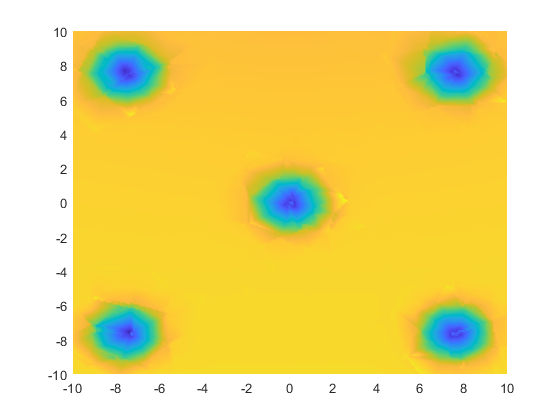

freqSelect = 4;
numPts = 201;
fieldPlot.y = field.y(1:numPts);
fieldPlot.Ex = reshape(field.Ex(3+freqSelect,:),[201,201]);
pcolor(real(fieldPlot.y), real(fieldPlot.y), abs(fieldPlot.Ex));
shading interp;


%plot3(field.y, field.z, field.Ex(4,:)),'o';

% % NO DC TERM IN RAW!
% field.freq = (data(:,1)).';
% field.posX 


## Raw Vector Approach

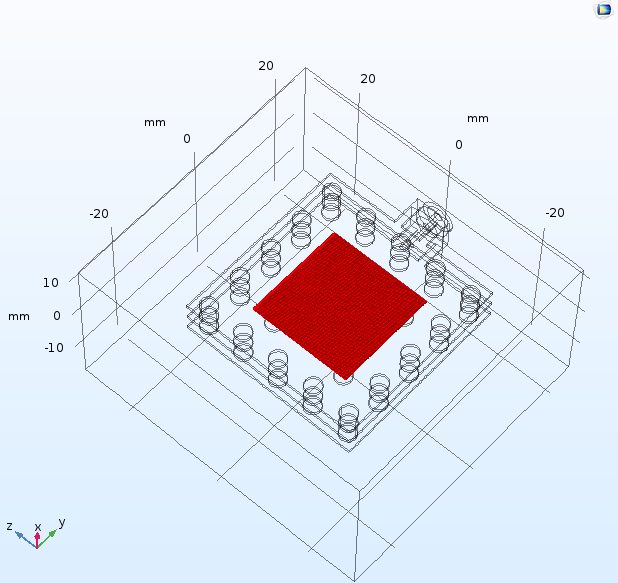

freqSelect = 161;
disp(['Chosen Frequency: ', num2str(field.freq(freqSelect)/c.giga), ' GHz'])

Chosen Frequency: 8.05 GHz


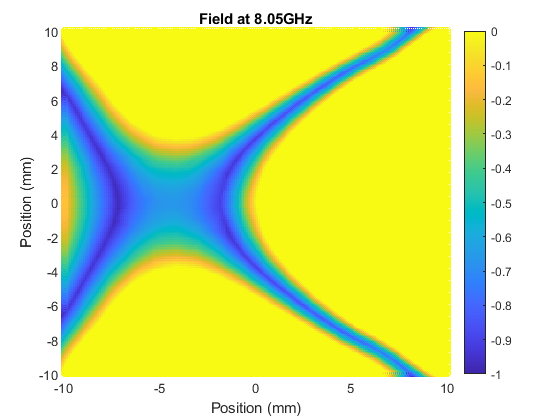



pointsize = 20;
fieldDC_Norm = abs(field.Ex(1,:)/field.Ex(1,1)); % Normalized electric field at 50 MHz normalized to a corner

%Normalized field to corner point 1 either directly plotted or as
%difference
fieldPlot = abs(field.Ex(freqSelect,:)/field.Ex(freqSelect,1)) - fieldDC_Norm;

%fieldPlot = abs(field.Ex(freqSelect,:)/field.Ex(freqSelect,1)) - fieldDC_Norm;

scatter3(real(field.y(:)), real(field.z(:)), fieldPlot , pointsize, fieldPlot) 
title(['Field at ', num2str(field.freq(freqSelect)/c.giga), 'GHz'])
view([0 90]);
shading interp;
colormap(parula)
colorbar
xlabel('Position (mm)')
ylabel('Position (mm)')

caxis([-1,0])

## Line Plot Input

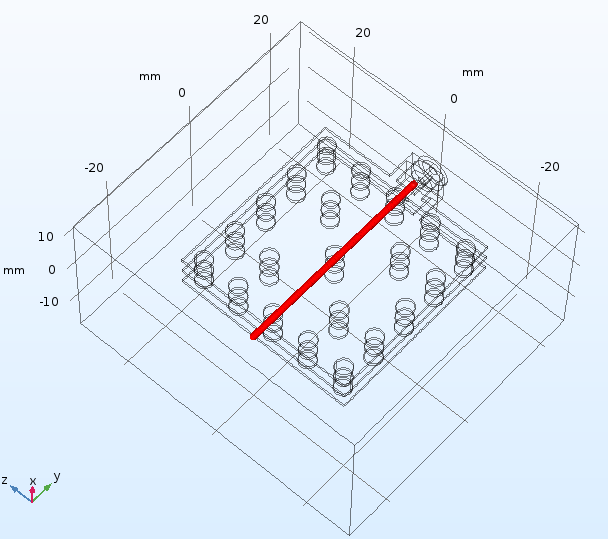

filename = 'xField_PropAxis_grid.txt'

filename = 'xField_PropAxis_grid.txt'

data=readtable(filename,'HeaderLines',9);
data=table2array(data);
sizeAr = size(data);
sizeY = sizeAr(1) ; % no header we remove
sizeF = sizeAr(2) - 3; %3 dimension columns we remove

propField.freq = field.freq;
propField.x = data(1,1);
propField.y = data(:,2);
propField.z = data(1,3);
propField.Ex = data(:,4:end);


% Manipulate
yRange = 1:401;
sizeYrange = size(yRange);
sizeYrange = sizeYrange(2)

sizeYrange = 401


freqRange = 1:100;

normField = abs(propField.Ex(yRange,:));

rescaleIndex =200;

normFieldRescaled = zeros(sizeYrange, sizeF);
%maxField = 1000;
for index = 1:sizeF
    normFieldRescaled(:,index) = normField(:,index)/abs(normField(rescaleIndex,index));
%     if(maxField < normFieldRescaled(end,index))
%         normFieldRescaled(:,index) = normFieldRescaled(:,index-1);
%     end
end

% Plot
plotField = log(normFieldRescaled)%.* real(propField.Ex)./abs(real(propField.Ex));

plotField =    -1.3066   -1.3059   -1.3046   -1.3029   -1.3006   -1.2979   -1.2947   -1.2909   -1.2867   -1.2820   -1.2768   -1.2711   -1.2650   -1.2584   -1.2515   -1.2442   -1.2367   -1.2292   -1.2220   -1.2159   -1.2127   -1.2174   -1.2844   -0.8019   -1.0554   -1.0716   -1.0677   -1.0573   -1.0437   -1.0279   -1.0104   -0.9916   -0.9714   -0.9501   -0.9275   -0.9036   -0.8785   -0.8522   -0.8244   -0.7953   -0.7647   -0.7325   -0.6986   -0.6630   -0.6255   -0.5859   -0.5441   -0.4999   -0.4531   -0.4034
   -1.2494   -1.2487   -1.2474   -1.2457   -1.2434   -1.2406   -1.2374   -1.2337   -1.2294   -1.2247   -1.2195   -1.2138   -1.2076   -1.2010   -1.1940   -1.1867   -1.1791   -1.1715   -1.1642   -1.1578   -1.1541   -1.1578   -1.2200   -0.7613   -1.0025   -1.0171   -1.0126   -1.0019   -0.9880   -0.9721   -0.9546   -0.9357   -0.9155   -0.8941   -0.8715   -0.8477   -0.8226   -0.7962   -0.7685   -0.7394   -0.7088   -0.6767   -0.6428   -0.6073   -0.5698   -0.5302   -0.4885   -0.4444   -0.3

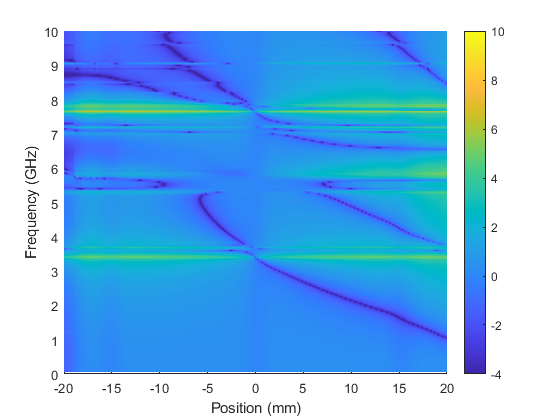

pcolor(real(propField.y(yRange)), (real(propField.freq)/c.giga), (plotField).');
shading interp;
colorbar;
caxis([-4,10])
xlabel('Position (mm)')
ylabel('Frequency (GHz)')
ylim([0,10])

%xlim([-10,10])
%clabel('Field Strength (V/m')

## Deflection Magnitude/Phase Plots

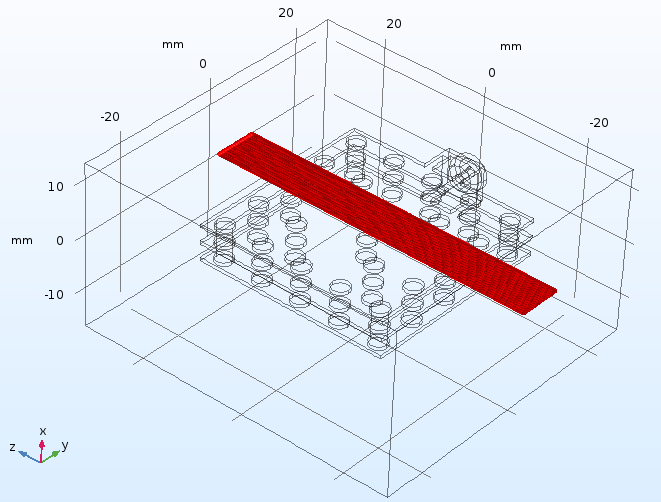

% Import
filename = 'xField_deflPaths_grid.txt'

filename = 'xField_deflPaths_grid.txt'

data=readtable(filename,'HeaderLines',9);
data=table2array(data);
sizeAr = size(data);
sizeY = sizeAr(1) ; % no header we remove
sizeF = sizeAr(2) - 3; %3 dimension columns we remove

deflField.freq = field.freq;
deflField.x = data(1,1);

% shape y
deflField.y = data(:,2);
yNum = ((deflField.y(end))-(deflField.y(1)))/(deflField.y(2)-deflField.y(1))+1;
deflField.y = deflField.y(1:yNum);

% shape z
deflField.z = data(:,3);
zNum = ((deflField.z(end))-(deflField.z(1)))/(deflField.z(1+yNum)-deflField.z(1))+1;
deflField.z = deflField.z(1:yNum:end);


% shape field and plot
freqSelect = 10;
disp(['Chosen Frequency: ', num2str(field.freq(freqSelect)/c.giga), ' GHz']);

Chosen Frequency: 0.5 GHz


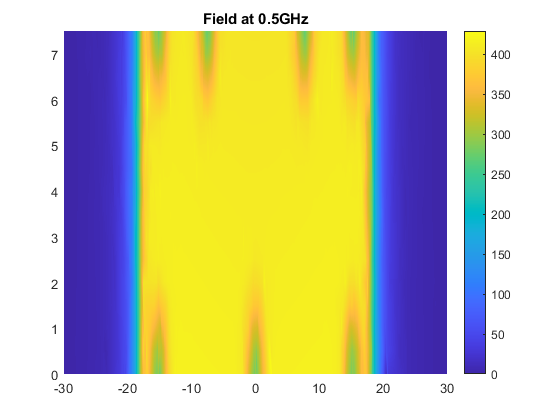


deflField.Ex = data(:,4:end).';
deflField.Ex = reshape(deflField.Ex(freqSelect,:),yNum,[]);
pcolor(real(deflField.z), real(deflField.y), abs(deflField.Ex).*(sign(real(deflField.Ex))))
title(['Field at ', num2str(field.freq(freqSelect)/c.giga), 'GHz'])
shading interp;
colorbar;

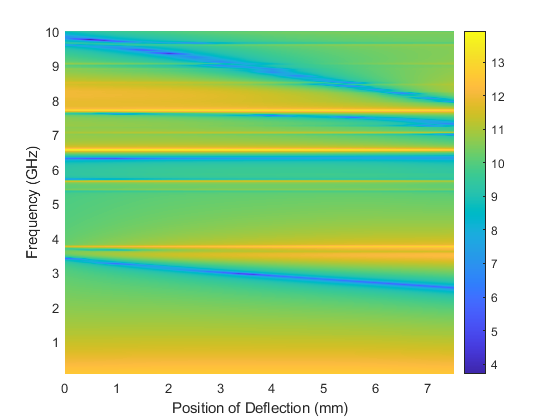

% Plot deflection as frequency and position
freqMax = 200;
for freqSelect = 1:freqMax
    deflField.Ex = data(:,4:end).';
    deflField.Ex = reshape(deflField.Ex(freqSelect,:),yNum,[]);
    defl(:,freqSelect) = sum(deflField.Ex,2);
end

pcolor(real(deflField.y), real(deflField.freq(1:freqMax))/c.giga,   log(abs(defl)).') %(sign(real(defl)).*abs(defl)).'
shading interp;
colorbar;
xlabel('Position of Deflection (mm)')
ylabel('Frequency (GHz)')

% Plot individual field
freqSelect1 = 52; field.freq(freqSelect1)

ans = 2.6000e+09

freqSelect2 = 59; field.freq(freqSelect2)

ans = 2.9500e+09

freqSelect3 = 184; field.freq(freqSelect3)

ans = 9.2000e+09

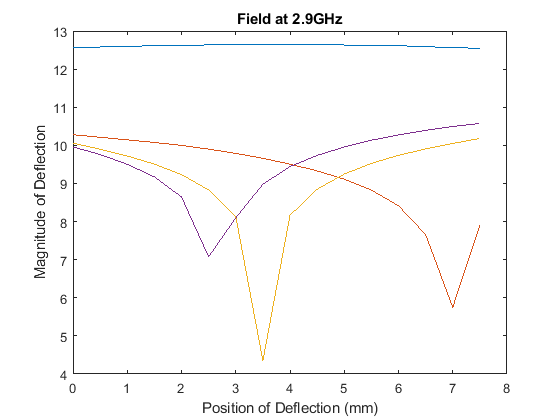

plot(deflField.y, log(abs(defl(:,[1, freqSelect1, freqSelect2, freqSelect3]))))
title(['Field at ', num2str(field.freq(freqSelect)/c.giga), 'GHz'])
xlabel('Position of Deflection (mm)')
ylabel('Magnitude of Deflection')

% Plot point as frequency
ySelect1 = 8; deflField.y(ySelect1)

ans = 3.5000

ySelect2 = 15; deflField.y(ySelect2)

ans = 7

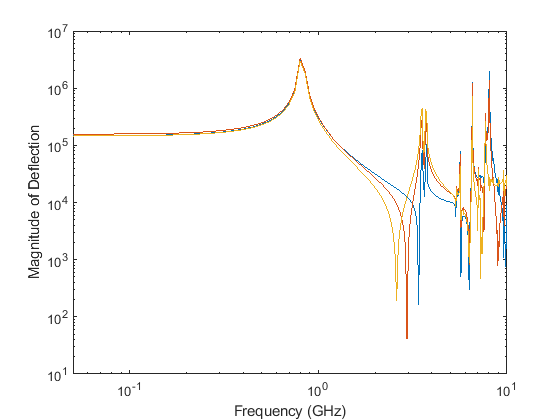


loglog(deflField.freq.'/c.giga, abs(defl([1,ySelect1, ySelect2],:)./(port.v.')))
%title(['Field at ', num2str(deflField.y(ySelect)), 'mm'])
xlabel('Frequency (GHz)')
ylabel('Magnitude of Deflection')

## Side Plot

filename = 'xField_sidePlane_grid.txt'

filename = 'xField_sidePlane_grid.txt'

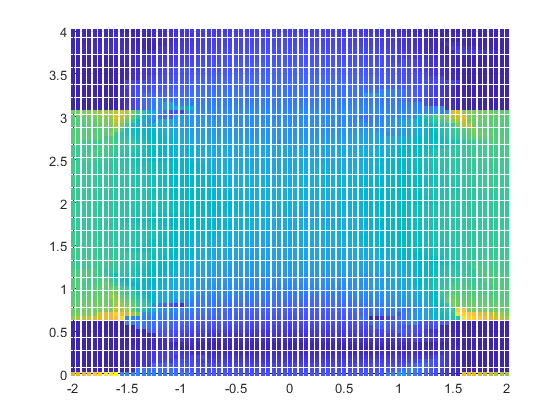

data=readtable(filename,'HeaderLines',9);
data=table2array(data);
propField.x = data(:,1);
propField.y = data(:,2);
propField.z = data(1,3);
propField.Ex = data(:,4:end).';

pointsize = 100;
fieldPlot = abs(propField.Ex(1,:)/propField.Ex(1,1)); % Normalized electric field at 50 MHz normalized to a corner


scatter3(real(propField.y(:)), real(propField.x(:)), fieldPlot , pointsize, fieldPlot, '.') 
view([0 90]);
shading interp;